## Zadanie 0

Rozwiązanie w formie skanu zeszytu.

## Zadanie 1

Domyślnie rysujemy x(t).

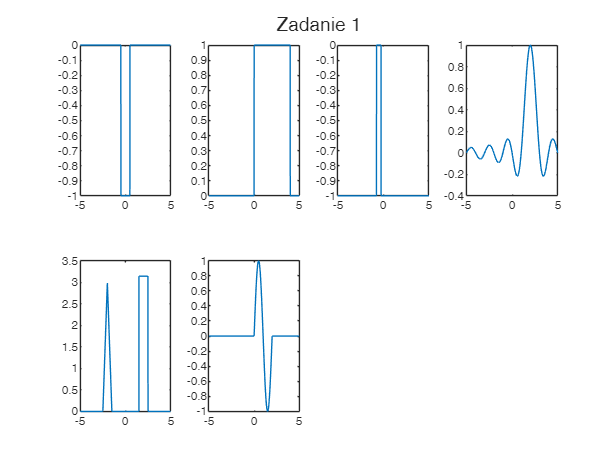

t=linspace(-5,5,1000);

funRys = @(x,t) x(t);
%funRys = @(x,t) x(2*t);
%funRys = @(x,t) x(-t);
%funRys = @(x,t) x(-t+3);

figure;
tiledlayout(2,4)

nexttile
plot(t,-funRys(@rectpuls,t))

nexttile
plot(t,funRys(@rectpuls,t/4-1/2))

nexttile
plot(t,funRys(@rectpuls,2*(t+1/2))-1)

nexttile
plot(t,funRys(@sinc,t-2))

xt = @(t) pi*rectpuls(t-2)+3*tripuls(t+2);
nexttile
plot(t,funRys(xt,t))

xt = @(t) sin(pi*t).*rectpuls(1/2*t-1/2);
nexttile
plot(t,funRys(xt,t))

sgtitle('Zadanie 1')

## Zadanie 2

syms t a x(t)
assume(a>0)

x(t) = heaviside(t)*exp(-a*t);
xp = 1/2*(x(t)+x(-t))

$$xp = \frac{\mathrm{heaviside}\left(-t\right)\,{\mathrm{e}}^{a\,t}}{2}+\frac{{\mathrm{e}}^{-a\,t}\,\mathrm{heaviside}\left(t\right)}{2}$$

xn = 1/2*(x(t)-x(-t))

$$xn = \frac{{\mathrm{e}}^{-a\,t}\,\mathrm{heaviside}\left(t\right)}{2}-\frac{\mathrm{heaviside}\left(-t\right)\,{\mathrm{e}}^{a\,t}}{2}$$

int(xp*xn,-Inf,Inf)

$$ans = 0$$

## Zadanie 3

syms t a f0 x(t)
assume(a>0)
assume(f0>0)


Moc sygnału typu cosinus za okres.

x(t) = cos(2*pi*f0*t);
f0*int(x^2,0,1/f0)

$$ans = \frac{1}{2}$$

Energia sygnału typu jednostronny exp.

x(t) = heaviside(t)*exp(-a*t);
int(x^2,-Inf,Inf)

$$ans = \frac{1}{2\,a}$$

Energia części cosinusa.

x(t) = 10*rectangularPulse(t/5)*cos(16*pi*t);
int(x^2,-Inf,Inf)

$$ans = 250$$

## Zadanie 4

Rozwiązanie w formie skanu PDF.

## Zadanie 5

Rozwiązanie w formie numerycznej

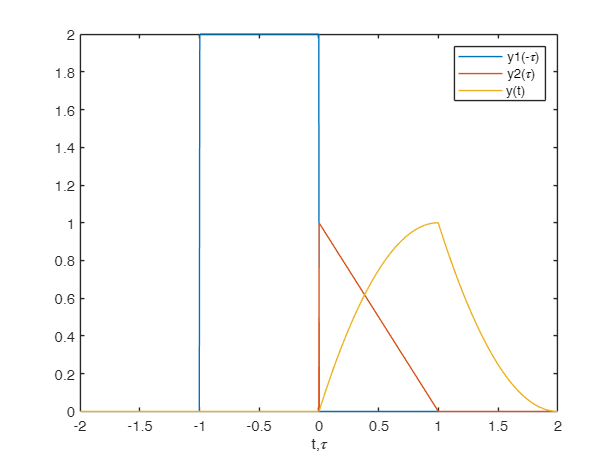

T = 1;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) 2*heaviside(t)-2*heaviside(t-T);
y2 = @(t) (T-t).*rectpuls((t-T/2)/T);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'})
xlabel('t,\tau')

## Zadanie 6

t = linspace(-1,1,1000);
dt = mean(diff(t));

xt = abs(t); %sygnal, ktory aproksymujemy

g1 = ones(size(t));
g2 = t;
g3 = 3/2*t.^2-1/2;

Liczymy energię sygnałów bazowych jako $E_# =\int_{-\infty \;}^{\infty \;} g_# {\left(t\right)}^2 \textrm{dt}$

Eg1 = sum(abs(g1).^2)*dt;
Eg2 = sum(abs(g2).^2)*dt;
Eg3 = sum(abs(g3).^2)*dt;

Współczynniki rozwinięcia liczymy jako $A_# =\frac{1}{E_# }\int_{-\infty \;}^{\infty \;} x\left(t\right)g_# \left(t\right)\textrm{dt}$

A1 = 1/Eg1*sum(xt.*g1)*dt

A1 = 0.5005

A2 = 1/Eg2*sum(xt.*g2)*dt

A2 = -8.9748e-18

A3 = 1/Eg3*sum(xt.*g3)*dt

A3 = 0.6269

Porównujemy aproksymację naszą metodą z metodą "[fit](https://www.mathworks.com/help/curvefit/fit.html)" wbudowaną w MATLAB. W naszej metodzie $\overset{~}{x\left(t\right)} =A_1 g_1 \left(t\right)+A_2 g_2 \left(t\right)+A_3 g_3 \left(t\right)$.

%%
figure;
plot(t,abs(t));
hold on;
plot(t, A1*g1+A2*g2+A3*g3);
eq1 = 'a1+a2*x+a3*((3/2*x^2-1/2))';
f1 = fit(t',abs(t)',eq1);

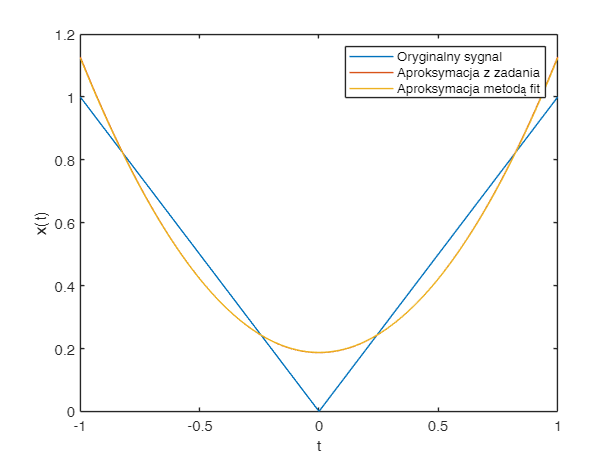

plot(t,f1(t))
xlabel('t')
ylabel('x(t)')
legend({'Oryginalny sygnal','Aproksymacja z zadania', 'Aproksymacja metodą fit'})

Można policzyć również średniokwadratowy błąd rozwinięcia jako $\Theta =\frac{1}{|a_1 -a_2 |}\int_{a_1 }^{a_2 } {\left\lbrack x\left(t\right)-\overset{~}{x\left(t\right)} \right\rbrack }^2 \textrm{dt}$

err = 1/diff(minmax(t))*sum((xt-(A1*g1+A2*g2+A3*g3)).^2)*dt

err = 0.0052

## Zadanie 7

Rozwiązanie działa tylko gdy t zaczyna się w 0.

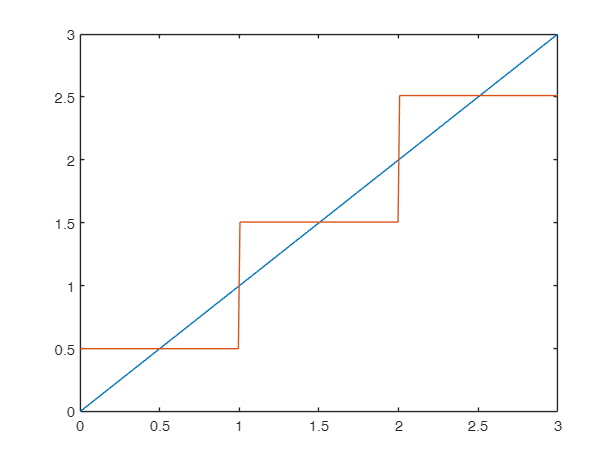



xt = @(t) t;

a1 = [1,-1,0];
a2 = [1,1,1];
a3 = [0,1,-2];

t = linspace(0,3,length(a1)*100);
dt = mean(diff(t));
da = diff(minmax(t))/length(a1);

a1Norm = sqrt(sum(a1.^2)*da);
e1 = a1/a1Norm;

e2 = a2-sum(e1.*a2)*e1*da;
e2Norm = sqrt(sum(e2.^2)*da);
e2 = e2/e2Norm;

e3 = a3-sum(e1.*a3)*e1*da-sum(e2.*a3)*e2*da;
e3Norm = sqrt(sum(e3.^2)*da);
e3 = e3/e3Norm;

L = length(a1);
dL = length(t)/L;
e1t = zeros(size(t));
e2t = zeros(size(t));
e3t = zeros(size(t));
for i=1:L
        e1t(dL*(i-1)+1:dL*(i)) = e1(i);
        e2t(dL*(i-1)+1:dL*(i)) = e2(i);
        e3t(dL*(i-1)+1:dL*(i)) = e3(i);
end

A1 = sum(xt(t).*e1t)*dt;
A2 = sum(xt(t).*e2t)*dt;
A3 = sum(xt(t).*e3t)*dt;

figure;
plot(t,xt(t));
hold on;
plot(t,A1*e1t+A2*e2t+A3*e3t)

Można policzyć również średniokwadratowy błąd rozwinięcia jako $\Theta =\frac{1}{|a_1 -a_2 |}\int_{a_1 }^{a_2 } {\left\lbrack x\left(t\right)-\overset{~}{x\left(t\right)} \right\rbrack }^2 \textrm{dt}$

err = 1/diff(minmax(t))*sum((xt(t)-(A1*e1t+A2*e2t+A3*e3t)).^2)*dt

err = 0.0842